**30/03/21**

**Miembros del equipo:**

**Maxine Annel Pacheco Ramírez A01551933**

**Kristen Aideé Pérez Alvarez A00829551**

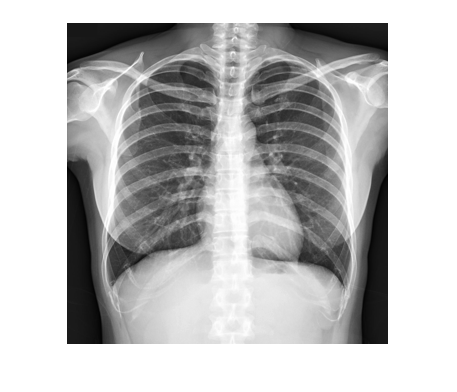


f=imread('radiograph1.jpg');
f=imresize(f,0.25);
f=double(f(:,:,1));
imshow(f,[])

edgex=[1,-1] %AQUI HACEMOS CONVOLUCION

edgex =      1    -1


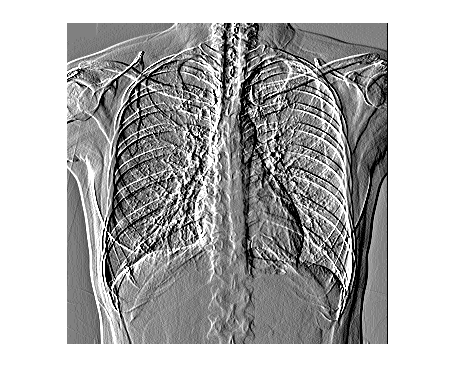

%edgex=[-1,1] %Derivadas al revés. Lo negativo es positivo AQUI HACEMOS
%CORRELACION
g1=conv2(f,edgex,'same');
imshow(g1,[-10,10]);

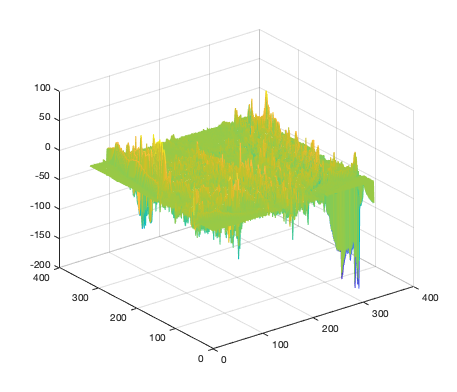

mesh(g1) %Aqui se logra observar una topografía

%Gris representa 0
%brillante-> obscuro = negativo
edgey=[-1 -2 -1;0,0,0;1,2,1]/8  %EN Y FILTRO DE SOVEN

edgey =    -0.1250   -0.2500   -0.1250
         0         0         0
    0.1250    0.2500    0.1250


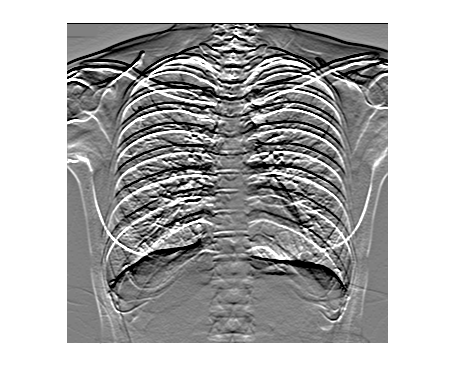

% edgey=[-1 -2 -1;0,0,0;1,2,1] %LE QUITE EL 8, Sin corregir por ganancia, esta mucho más fuerte pq no hicimos la corrección. Correcto, se debe dividir entre 8 
g2=conv2(f,edgey,'same');
imshow(g2,[-10,10])

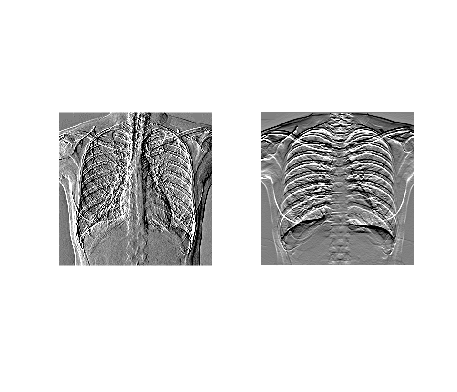

%Costillas, se ven mejor en la y 
%en la x se ve mejor el corazón 
figure(2)
subplot(1,2,1)
imshow(g1,[-10,10])
subplot(1,2,2)
imshow(g2,[-10,10])


figure(3)
subplot(1,1,1)

edgex=[1,0,-1;2,0,-2;1,0,-1]/8 % se hace derivada en x con sobel

edgex =     0.1250         0   -0.1250
    0.2500         0   -0.2500
    0.1250         0   -0.1250


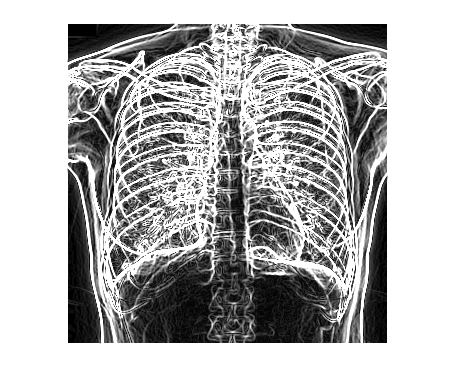

gx=conv2(f,edgex,'same'); % se hace convolución x
gy=conv2(f,edgey,'same'); % se hace convolución y
%mag=abs(gx)+abs(gy); % se quitó esta manera de sacar la magnitud porque lo más correcto es con la raíz cuadrada
mag=(sqrt((gx.^2)+(gy.^2))); % sacar la magnitud con la raíz cuadrada
imshow(mag,[0,10]); % en este proceso se hace una interpretación isotrópica